% This real-time script is used to demonstrate the dual spectral reconstruction method. 
% It communicates with the FPGA acquisition card via a serial port to read the test results 
% of responsivity and relaxation time from the corresponding registers on the FPGA.

% Version 1.10
% by Xinchuan Du & Yi Cui
% Update 3-Jan-2024

% The serial port is initialized and detected
serial_port = serialport('COM7');
set(serial_port, 'BaudRate', 115200); % High-speed serial port was used for ITR data acquisition
fopen(serial_port); % Serial connection is established and the communication indicator lights up
if strcmp(serial_port.Status, 'open') % Abnormal yield analysis
    disp('The serial port is open, and communicate with slave FPGA.');
else
    error('The serial port is not open or occupied!');
end
% Write the instruction configuration register to the slave FPGA
registerData = [0x2000, 0x4DA0, 0x636E, 0x8100, 0xA1BF]; % Configure the data for registers 1-5
% The register communication uses the uint16 format, where the first three bits represent the 
% register address and the remaining 13 bits represent the register value or status configuration.
% Register 1 is for gate voltage scan lower limit, Register 2 is for gate voltage scan upper limit,
% Register 3 is for scan speed, Register 4 is for bias, and Register 5 is for status settings.
for i = 1:5
    fwrite(serial_port, uint8(registerData(i)), 'uint16');
end

% Write the command to the downstream device to start the operation.
% Achieve it by updating the status bit of Register 5.
fwrite(serial_port, uint16(0xA1FF), 'uint16');

% Polling the status register of the slave FPGA.
status = bitand(fread(serial_port, 1, 'uint16'), 0x0040);
while status  % Continue polling when the work of the slave FPGA is not completed
    status = bitand(fread(serial_port, 1, 'uint16'), 0x0040);
end

% Data readout and CRC verification
rawdataMatrix = zeros(2, 1);
fwrite(serial_port, uint16(A2BF), 'uint16');
for i = 1:2
    data = fread(serial_port, 2, 'uint16'); % Read data from two data registers
    crc = crc32(data); % CRC verification
    if crc == fread(serial_port, 1, 'uint32') % Pass the check
        rawdataMatrix(i, :) = typecast(uint8(data), 'uint16');
    else
        error('CRC validation failed!');
        fwrite(serial_port, uint16(0xB1FF), 'uint16'); % Roll back data sent
    end
end
fclose(serial_port); % Cose the serial port
[pdsignal, edsignal] = decode_rawMat(rawdataMatrix); % Decode pd and ed signal from raw data Matrix


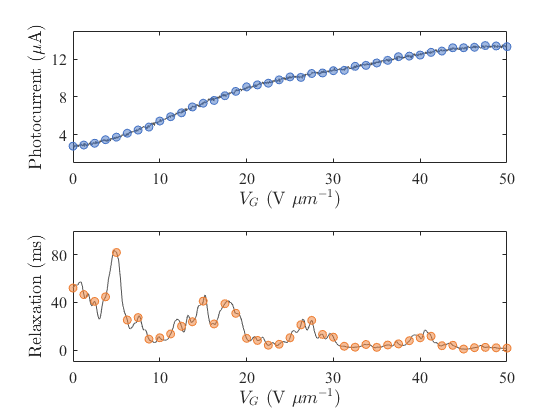

% Signal transformation, interpolation and normalization
relaxation_interp = interp1(linspace(0,50,200001),pdsignal,linspace(0,50,4001),"makima","extrap");
responsivity_interp = interp1(linspace(0,50,200001),edsignal,linspace(0,50,4001),"makima","extrap");

% Plot relaxation_interp and responsivity_interp (Fig3 subgraph)
Vg = linspace(0,50,4001);
subplot(211);
plot(Vg,responsivity_interp,'-',"Color",'#555555');xlim([0,50]);ylim([1 15]);hold on;
xlabel('$V_G$ (V $\mu m^{-1}$)',"Interpreter","latex");
set(gca,'xtick',[0 10 20 30 40 50],"FontName","Times New Roman");
ylabel('Photocurrent ($\mu$A)',"Interpreter","latex");
set(gca,'ytick',[4 8 12],"FontName","Times New Roman","FontSize",12);
s1 = scatter(Vg(1:100:4001),responsivity_interp(1:100:4001),'filled',"MarkerFaceColor",'#4472C4',"MarkerEdgeColor",'#4472C4');hold off;
s1.AlphaData = 0.5*ones(size(Vg(1:100:4001)));s1.MarkerFaceAlpha = 'flat';
subplot(212);
plot(Vg,relaxation_interp,'-',"Color",'#555555');xlim([0,50]);ylim([-10 100]);hold on;
xlabel('$V_G$ (V $\mu m^{-1}$)',"Interpreter","latex");
set(gca,'xtick',[0 10 20 30 40 50],"FontName","Times New Roman");
ylabel('Relaxation (ms)',"Interpreter","latex");
set(gca,'ytick',[0 40 80],"FontName","Times New Roman","FontSize",12);
s2 = scatter(Vg(1:100:4001),relaxation_interp(1:100:4001),'filled',"MarkerFaceColor",'#ED7D31',"MarkerEdgeColor",'#ED7D31');hold off;
s2.AlphaData = 0.5*ones(size(Vg(1:100:4001)));s2.MarkerFaceAlpha = 'flat'; hold off;

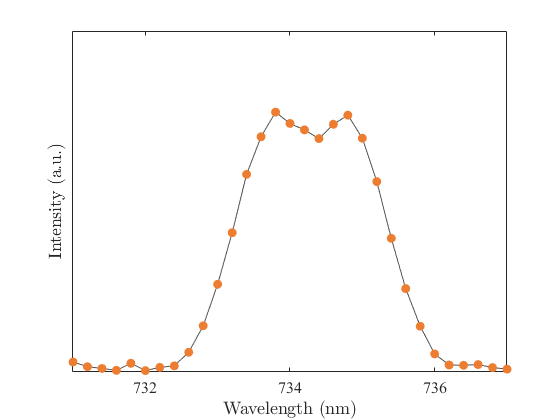

% Merge dual signal as network input
net_input = [relaxation_interp,...
             mean(relaxation_interp),...
             var(relaxation_interp),...
             responsivity_interp,...
             mean(responsivity_interp),...
             var(responsivity_interp)]';
% Load the trained network
load('traindNet_[21-June-2023].mat');
% Tusing neural network reconstrcut spectrum
reconstructed_spectrum = net(net_input);
% plot the reconstructed spectrum as Figure 3d
lambda = linspace(450,850,2001);
figure;plot(lambda,reconstructed_spectrum,'-',"Color",'#555555');hold on;
sl = scatter(lambda,reconstructed_spectrum,'filled',"MarkerFaceColor",'#ED7D31',"MarkerEdgeColor",'#ED7D31');
xlim([731,737]);ylim([0 15]);
xlabel('Wavelength (nm)',"Interpreter","latex");
set(gca,'xtick',[732 734 736],"FontName","Times New Roman");
ylabel('Intensity (a.u.)',"Interpreter","latex");
set(gca,'ytick',[],"FontName","Times New Roman","FontSize",12);hold off;